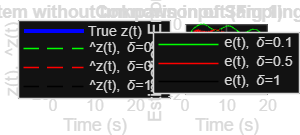

clear; clc; close all;

%% 1. System Parameters (Section V)
A = [-2, 1, 0; 1, -3, 1; 0, 0, -1];
B = [1; 1; 1];
C = [1, 0, 0; 0, 1, 0];
F = [0; 1; 1];
L = [1, 1, 0]; % Estimating z = x1 + x2

% Simulation Settings
t_end = 20;
dt = 0.001; 
time = 0:dt:t_end;

% Toggle Settings
include_unknown_input = true;
deltas = [0.1, 0.5, 1.0];      % Sampling periods to compare
colors = {'g', 'r', 'k'};      

%% 2. Design Matrices (From Section V-A text)
N = -2.4388;
H = 2.4148;
J = [1.0597, 2.4148];
E = [-1.4148, 1];

u_t = @(t_val) sin(t_val);


% Plant: dx/dt = Ax + Bu + Fd
plant_dynamics = @(t, x, u, d) A*x + B*u + F*d;
% Observer: dw/dt = Nw + Hu + Jy(tk)
obs_dynamics = @(w, u, yk) N*w + H*u + J*yk;

%% 4. Simulation and Plotting
figure('Color', 'w', 'Position', [100, 100, 1000, 450]);

% Subplot 1: z(t) and z_hat(t)
subplot(1,2,1); hold on;
% Subplot 2: Estimation Error e(t)
subplot(1,2,2); hold on;

for d_idx = 1:length(deltas)
    delta = deltas(d_idx);
    
    % Initialize states
    x = [0; 0; 0]; 
    w = 1; % Initial observer state as per paper
    y_k = C * x;
    last_sample_time = 0;
    
    % Storage
    z_hist = zeros(size(time));
    z_hat_hist = zeros(size(time));
    
    for i = 1:length(time)
        t = time(i);
        
        % --- Discrete Sampling & Correction ---
        if t >= last_sample_time + delta
            z_hat_minus = w + E * y_k;
            y_k = C * x;
            w = z_hat_minus - E * y_k; % Eq 6: Correction Term
            last_sample_time = t;
        end
        
        % --- Current Inputs ---
        curr_u = u_t(t);
        if include_unknown_input
            d_val = -exp(0.1*t) * (3*sin(0.001*t + pi/6) + 1);
        else
            d_val = 0;
        end
        
        % --- RK4 Integration for Plant (x) ---
        k1_x = plant_dynamics(t, x, curr_u, d_val);
        k2_x = plant_dynamics(t + dt/2, x + dt/2*k1_x, u_t(t + dt/2), d_val);
        k3_x = plant_dynamics(t + dt/2, x + dt/2*k2_x, u_t(t + dt/2), d_val);
        k4_x = plant_dynamics(t + dt, x + dt*k3_x, u_t(t + dt), d_val);
        x_next = x + (dt/6) * (k1_x + 2*k2_x + 2*k3_x + k4_x);
        
        % --- RK4 Integration for Observer (w) ---
        k1_w = obs_dynamics(w, curr_u, y_k);
        k2_w = obs_dynamics(w + dt/2*k1_w, u_t(t + dt/2), y_k);
        k3_w = obs_dynamics(w + dt/2*k2_w, u_t(t + dt/2), y_k);
        k4_w = obs_dynamics(w + dt*k3_w, u_t(t + dt), y_k);
        w_next = w + (dt/6) * (k1_w + 2*k2_w + 2*k3_w + k4_w);
        
        % Save Current Estimates
        z_hist(i) = L * x;
        z_hat_hist(i) = w + E * y_k;
        
        % Update for next step
        x = x_next;
        w = w_next;
    end
    
    % --- Plotting ---
    subplot(1,2,1);
    if d_idx == 1
        plot(time, z_hist, 'b', 'LineWidth', 2, 'DisplayName', 'True z(t)');
    end
    plot(time, z_hat_hist, colors{d_idx}, 'LineStyle', '--', ...
        'DisplayName', ['\^z(t), \delta=' num2str(delta)]);
    
    subplot(1,2,2);
    plot(time, z_hist - z_hat_hist, colors{d_idx}, ...
        'DisplayName', ['e(t), \delta=' num2str(delta)]);
end

%% 5. Formatting
subplot(1,2,1); grid on; xlabel('Time (s)'); ylabel('z(t), \^z(t)');
legend('Location', 'best');
title(sprintf('Linear System without unknown input (%s)', iif(include_unknown_input, 'Fig 1', 'Fig 2')));

subplot(1,2,2); grid on; xlabel('Time (s)'); ylabel('Estimation Error');
legend('Location', 'best');
title('Comparison of Sampling Times');


function res = iif(cond, val1, val2)
    if cond, res = val1; else, res = val2; end
end